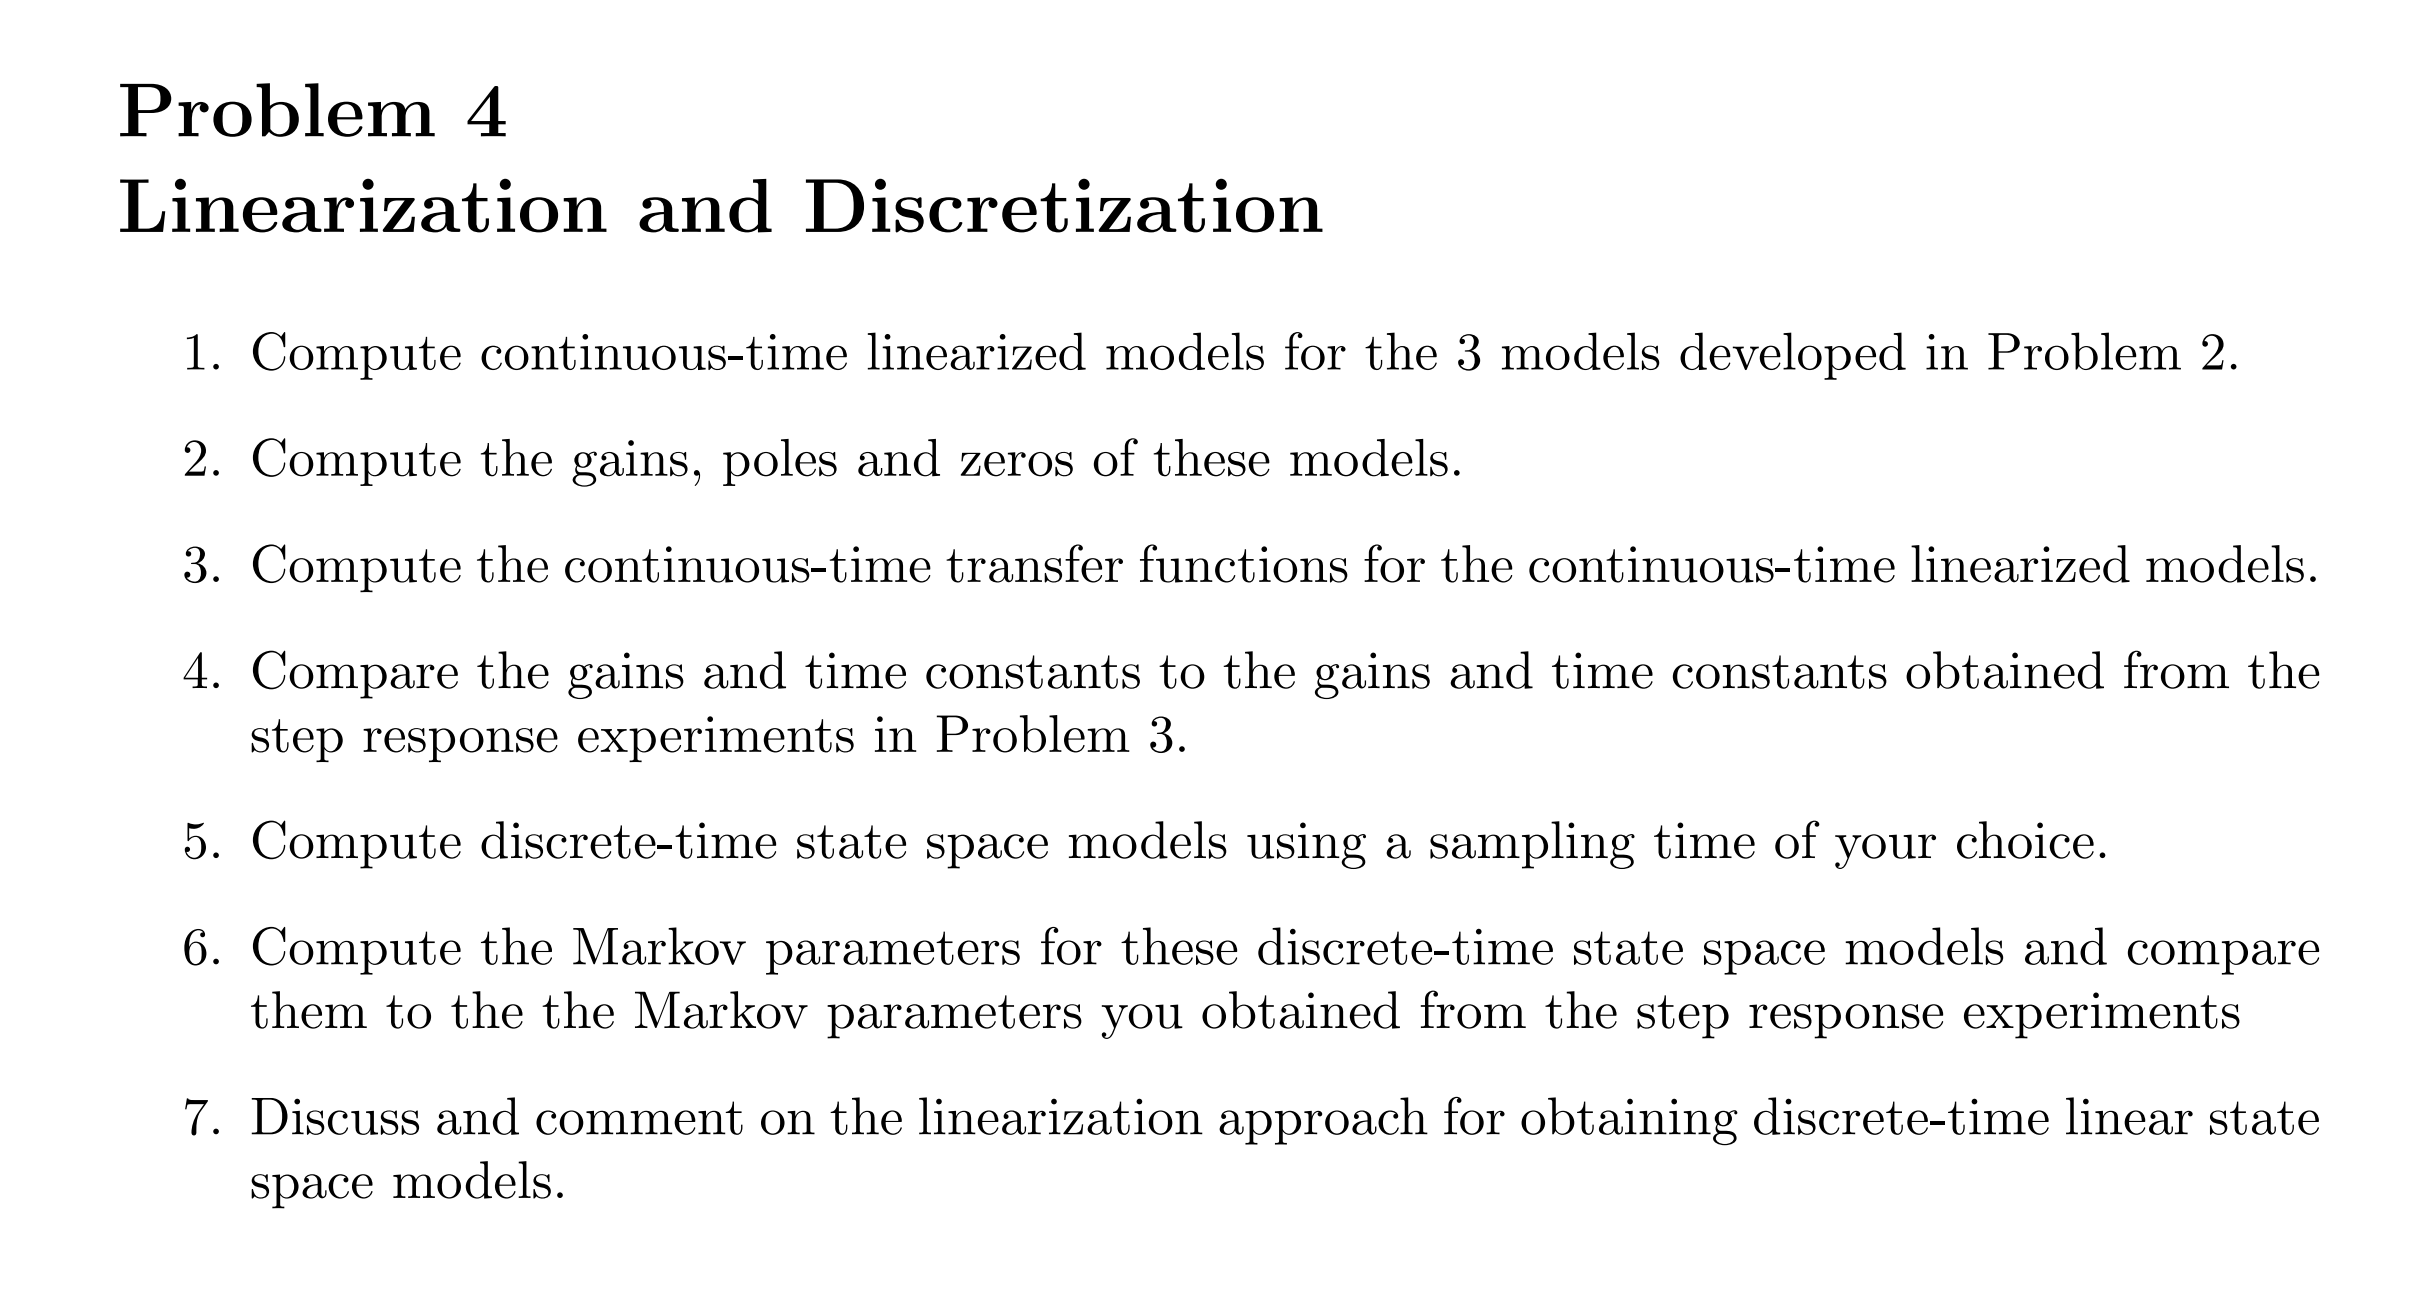

% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3 1.2272

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3 380

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1 0.45
gamma2 = 0.40; % Flow distribution constant. Valve 2 0.40
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------
%a3 a4:1.2272 Non-minimum phase system
%a3 a4:8 Minimum phase system

%steady-state
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
F1=300;
F2=300;
F3=250;
F4=250;
us = [F1;F2]; % [cm3/s] Flow rates
ds = [F3;F4]; % [cm3/s] Flow rates
xs0 = [5000; 5000; 5000; 5000]; % [g] Initial guess on xs
xs = fsolve(@ModifiedFourTankSystemWrap,xs0,[],us,ds,p)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    4.1068
    3.6822
    2.3787
    2.2157


ys = FourTankSystemSensor(xs,p)

ys =   108.0357
   96.8675
   62.5759
   58.2863


zs = FourTankSystemOutput(xs,p)

zs =   108.0357
   96.8675


%deterministic disturbance
syms x1 x2 x3 x4 u1 u2 d1 d2
m = [x1;x2;x3;x4]; % Mass of liquid in each tank [g]
F = [u1;u2;d1;d2]; % Flow rates in pumps [cm3/s]
a = p(1:4,1); % Pipe cross sectional areas [cm2]
A = p(5:8,1); % Tank cross sectional areas [cm2]
gamma = p(9:10,1); % Valve positions [-]
g = p(11,1); % Acceleration of gravity [cm/s2]
rho = p(12,1); % Density of water [g/cm3]

% Inflows

qin(1,1) = gamma(1)*F(1); % Inflow from valve 1 to tank 1 [cm3/s]
qin(2,1) = gamma(2)*F(2); % Inflow from valve 2 to tank 2 [cm3/s]
qin(3,1) = (1-gamma(2))*F(2); % Inflow from valve 2 to tank 3 [cm3/s]
qin(4,1) = (1-gamma(1))*F(1); % Inflow from valve 1 to tank 4 [cm3/s]
% Out_finallows
h = m./(rho*A); % Liquid level in each tank [cm]
qout = a.*sqrt(2*g*h); % Out_finallow from each tank [cm3/s]
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1))+F(3); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1))+F(4); % Mass balance Tank 4
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F],[xs;us;ds]),4))

Ass =    -0.0069         0    0.0090         0
         0   -0.0073         0    0.0094
         0         0   -0.0090         0
         0         0         0   -0.0094


Bss=eval(vpa(subs(jacobian(fx,F(1:2)),[m;F],[xs;us;ds]),4))

Bss =     0.4500         0
         0    0.4000
         0    0.6000
    0.5500         0


Bdss=eval(vpa(subs(jacobian(fx,F(3:4)),[m;F],[xs;us;ds]),4))

Bdss =      0     0
     0     0
     1     0
     0     1


Css=eval(vpa(subs(jacobian(gx,m),[m;F],[xs;us;ds]),4))

Css =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Czss=Css(1:2,:)

Czss =     0.0026         0         0         0
         0    0.0026         0         0


Dss=eval(vpa(subs(jacobian(gx,F(1:2)),[m;F],[xs;us;ds]),4))

Dss =      0     0
     0     0
     0     0
     0     0


Dzss=Dss(1:2,:)

Dzss =      0     0
     0     0


%stocastic disturbance
%dx=f(x,u)dt+gd(x,u)dw
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1)); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1)); % Mass balance Tank 4
gd(1,1) = F(1);
gd(2,1) = F(2);
gd(3,1) = F(3);
gd(4,1) = F(4);
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F(1:2)],[xs;us]),4))

Ass =    -0.0069         0    0.0090         0
         0   -0.0073         0    0.0094
         0         0   -0.0090         0
         0         0         0   -0.0094


Bss=eval(vpa(subs(jacobian(fx,F(1:2)),[m;F(1:2)],[xs;us]),4))

Bss =     0.4500         0
         0    0.4000
         0    0.6000
    0.5500         0


Bdss=eval(vpa(subs(jacobian(gd,F(3:4)),[m;F],[xs;us;ds]),4))

Bdss =      0     0
     0     0
     1     0
     0     1


Css=eval(vpa(subs(jacobian(gx,m),[m;F(1:2)],[xs;us]),4))

Css =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Czss=Css(1:2,:)

Czss =     0.0026         0         0         0
         0    0.0026         0         0


Dss=eval(vpa(subs(jacobian(gx,F(1:2)),[m;F(1:2)],[xs;us]),4))

Dss =      0     0
     0     0
     0     0
     0     0


Dzss=Dss(1:2,:)

Dzss =      0     0
     0     0


%gain pole zeros
sys_ss=ss(Ass,Bss,Css,Dss);
[z_deter_z,p_deter_z,k_deter_z] = zpkdata(sys_ss)

z_deter_z = 4×2 cell 数组
    {0×1 double}    {0×1 double}
    {0×1 double}    {0×1 double}
    {0×1 double}    {0×1 double}
    {0×1 double}    {0×1 double}


p_deter_z = 4×2 cell 数组
    {[ -0.0069]}    {2×1 double}
    {2×1 double}    {[ -0.0073]}
    {0×1 double}    {[ -0.0090]}
    {[ -0.0094]}    {0×1 double}


k_deter_z =     0.0012    0.0000
    0.0000    0.0011
         0    0.0016
    0.0014         0


%From state space to transfer function
Ts=4;
[num_c_u1,den_c_u1]=ss2tf(Ass,Bss,Css,Dss,1);
[num_c_u2,den_c_u2]=ss2tf(Ass,Bss,Css,Dss,2);
G_c_u1_y1=minreal(tf(num_c_u1(1,:),den_c_u1));
G_c_u1_y2=minreal(tf(num_c_u1(2,:),den_c_u1));
G_c_u1_y3=minreal(tf(num_c_u1(3,:),den_c_u1));
G_c_u1_y4=minreal(tf(num_c_u1(4,:),den_c_u1));

G_c_u2_y1=minreal(tf(num_c_u2(1,:),den_c_u2));
G_c_u2_y2=minreal(tf(num_c_u2(2,:),den_c_u2));
G_c_u2_y3=minreal(tf(num_c_u2(3,:),den_c_u2));
G_c_u2_y4=minreal(tf(num_c_u2(4,:),den_c_u2));

G_c_u1_y1_zpk=zpk(G_c_u1_y1)

G_c_u1_y1_zpk =
 
    0.001184
  ------------
  (s+0.006879)
 
Continuous-time zero/pole/gain model.



G_c_u1_y2_zpk=zpk(G_c_u1_y2)

G_c_u1_y2_zpk =
 
         1.3552e-05
  -------------------------
  (s+0.009365) (s+0.007265)
 
Continuous-time zero/pole/gain model.



G_c_u1_y3_zpk=zpk(G_c_u1_y3)

G_c_u1_y3_zpk =
 
  0
 
Static gain.



G_c_u1_y4_zpk=zpk(G_c_u1_y4)

G_c_u1_y4_zpk =
 
   0.0014471
  ------------
  (s+0.009365)
 
Continuous-time zero/pole/gain model.




G_c_u2_y1_zpk=zpk(G_c_u2_y1)

G_c_u2_y1_zpk =
 
         1.4267e-05
  -------------------------
  (s+0.009038) (s+0.006879)
 
Continuous-time zero/pole/gain model.



G_c_u2_y2_zpk=zpk(G_c_u2_y2)

G_c_u2_y2_zpk =
 
   0.0010524
  ------------
  (s+0.007265)
 
Continuous-time zero/pole/gain model.



G_c_u2_y3_zpk=zpk(G_c_u2_y3)

G_c_u2_y3_zpk =
 
   0.0015786
  ------------
  (s+0.009038)
 
Continuous-time zero/pole/gain model.



G_c_u2_y4_zpk=zpk(G_c_u2_y4)

G_c_u2_y4_zpk =
 
  0
 
Static gain.



[z_c_u1_y1,p_c_u1_y1,k_c_u1_y1]=zpkdata(G_c_u1_y1);
[z_c_u1_y2,p_c_u1_y2,k_c_u1_y2]=zpkdata(G_c_u1_y2);
[z_c_u1_y3,p_c_u1_y3,k_c_u1_y3]=zpkdata(G_c_u1_y3);
[z_c_u1_y4,p_c_u1_y4,k_c_u1_y4]=zpkdata(G_c_u1_y4);

[z_c_u2_y1,p_c_u2_y1,k_c_u2_y1]=zpkdata(G_c_u2_y1);
[z_c_u2_y2,p_c_u2_y2,k_c_u2_y2]=zpkdata(G_c_u2_y2);
[z_c_u2_y3,p_c_u2_y3,k_c_u2_y3]=zpkdata(G_c_u2_y3);
[z_c_u2_y4,p_c_u2_y4,k_c_u2_y4]=zpkdata(G_c_u2_y4);

gain_c_u1_y1=dcgain(G_c_u1_y1)

gain_c_u1_y1 = 0.1721

gain_c_u1_y2=dcgain(G_c_u1_y2)

gain_c_u1_y2 = 0.1992

gain_c_u1_y3=dcgain(G_c_u1_y3)

gain_c_u1_y3 = 0

gain_c_u1_y4=dcgain(G_c_u1_y4)

gain_c_u1_y4 = 0.1545


gain_c_u2_y1=dcgain(G_c_u2_y1)

gain_c_u2_y1 = 0.2295

gain_c_u2_y2=dcgain(G_c_u2_y2)

gain_c_u2_y2 = 0.1449

gain_c_u2_y3=dcgain(G_c_u2_y3)

gain_c_u2_y3 = 0.1747

gain_c_u2_y4=dcgain(G_c_u2_y4)

gain_c_u2_y4 = 0

%Compute discrete-time state space models
Ts = 4; 
[Ad,Bd]=c2dzoh(Ass,Bss,Ts)

Ad =     0.9729         0    0.0350         0
         0    0.9714         0    0.0362
         0         0    0.9645         0
         0         0         0    0.9632


Bd =     1.7755    0.0425
    0.0403    1.5770
         0    2.3571
    2.1593         0


[Ad,Bd_d]=c2dzoh(Ass,Bdss,Ts)

Ad =     0.9729         0    0.0350         0
         0    0.9714         0    0.0362
         0         0    0.9645         0
         0         0         0    0.9632


Bd_d =     0.0708         0
         0    0.0733
    3.9286         0
         0    3.9260


Gw_d=Bd_d;

%Compute the Markov parameters for these discrete-time state space models
H_0=Dss;
H_1=Css*Bd;
H_2=Css*Ad^1*Bd;
H_3=Css*Ad^2*Bd;
H_4=Css*Ad^3*Bd;
H_5=Css*Ad^4*Bd;
H_lin=[];
mp_lin_u1_y1=[];
mp_lin_u1_y2=[];
mp_lin_u1_y3=[];
mp_lin_u1_y4=[];
mp_lin_u2_y1=[];
mp_lin_u2_y2=[];
mp_lin_u2_y3=[];
mp_lin_u2_y4=[];
for i=1:100
    H_temp=Css*(Ad^(i-1))*Bd;
    H_lin=[H_lin,H_temp];
    mp_lin_u1_y1=[mp_lin_u1_y1,H_temp(1,1)];
    mp_lin_u1_y2=[mp_lin_u1_y2,H_temp(2,1)];
    mp_lin_u1_y3=[mp_lin_u1_y3,H_temp(3,1)];
    mp_lin_u1_y4=[mp_lin_u1_y4,H_temp(4,1)];
    mp_lin_u2_y1=[mp_lin_u2_y1,H_temp(1,2)];
    mp_lin_u2_y2=[mp_lin_u2_y2,H_temp(2,2)];
    mp_lin_u2_y3=[mp_lin_u2_y3,H_temp(3,2)];
    mp_lin_u2_y4=[mp_lin_u2_y4,H_temp(4,2)];
end

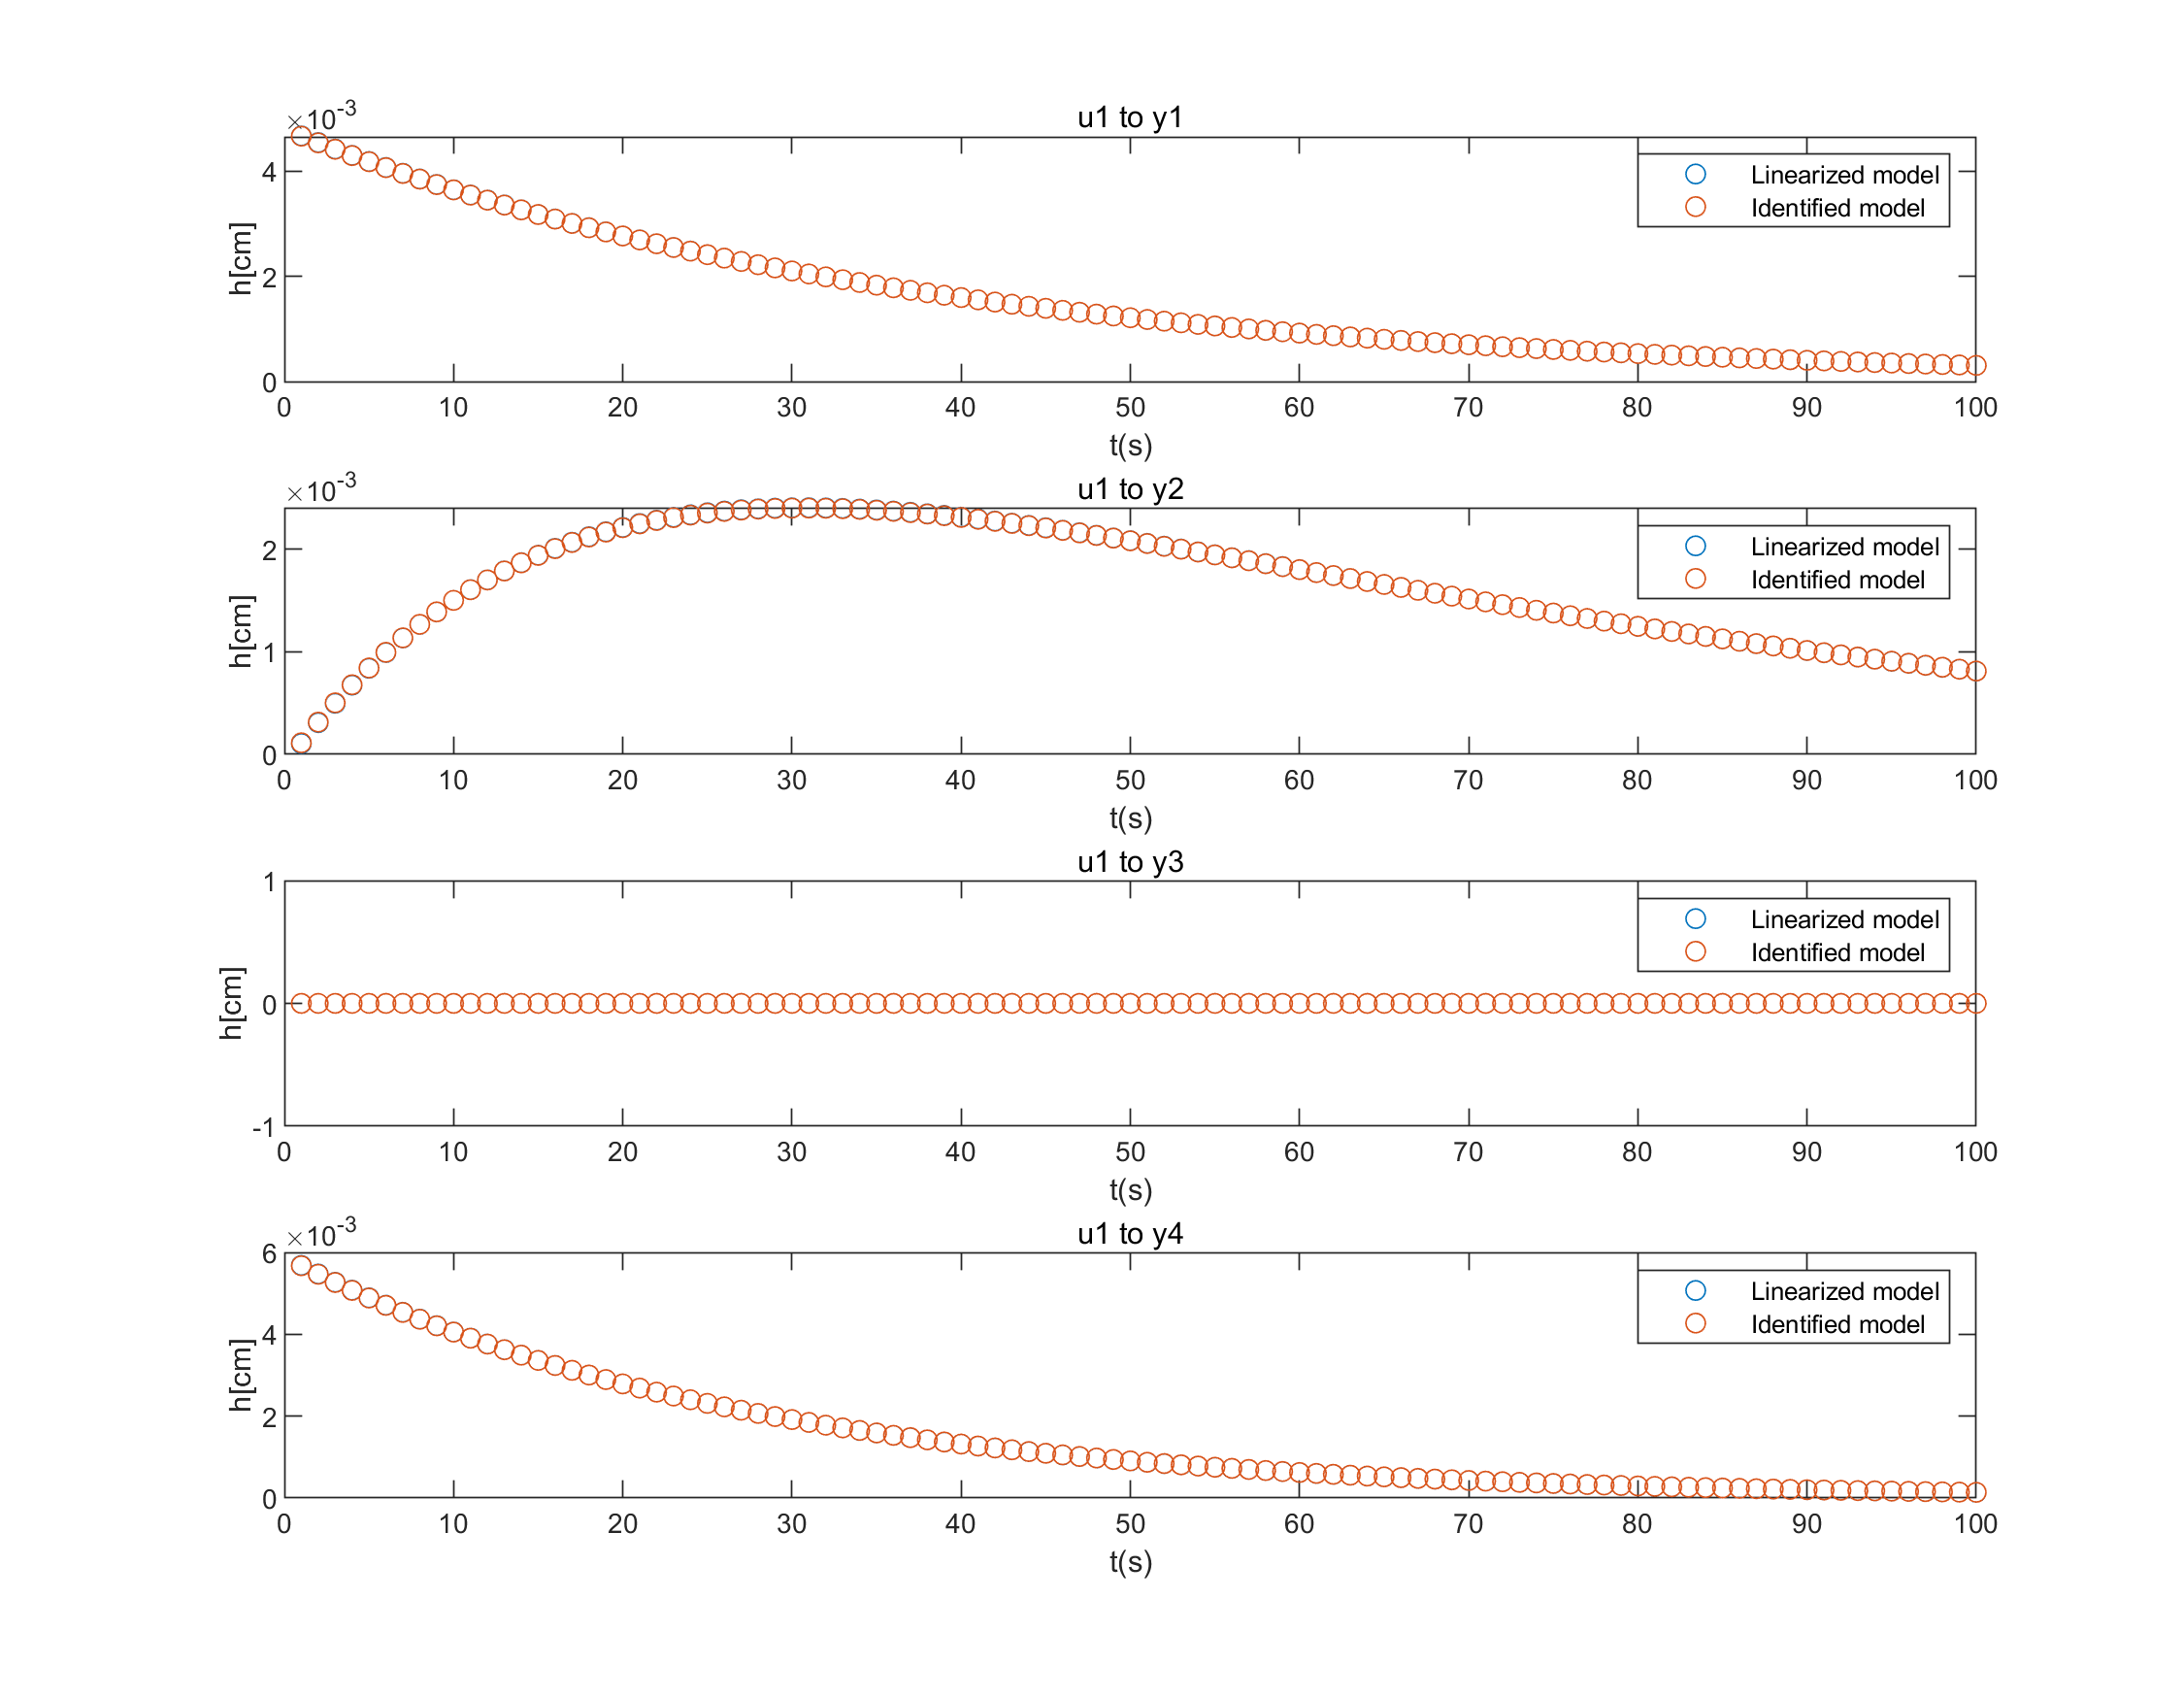

%plot the markov parameter
t_mp=1:100;
figure;
width=900;
height=700;
left=100;
bottem=100;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t_mp,mp_lin_u1_y1,'o',t_mp,mp_u1_y1,'o')
title('u1 to y1')
xlabel('t(s)');
ylabel('h[cm]');
legend("Linearized model","Identified model","Location", 'Northeast');
subplot(4,1,2)
plot(t_mp,mp_lin_u1_y2,'o',t_mp,mp_u1_y2,'o')
title('u1 to y2')
xlabel('t(s)');
ylabel('h[cm]');
legend("Linearized model","Identified model","Location", 'Northeast');
subplot(4,1,3)
plot(t_mp,mp_lin_u1_y3,'o',t_mp,mp_u1_y3,'o')
title('u1 to y3')
xlabel('t(s)');
ylabel('h[cm]');
legend("Linearized model","Identified model","Location", 'Northeast');
subplot(4,1,4)
plot(t_mp,mp_lin_u1_y4,'o',t_mp,mp_u1_y4,'o')
title('u1 to y4')
xlabel('t(s)');
ylabel('h[cm]');
legend("Linearized model","Identified model","Location", 'Northeast');

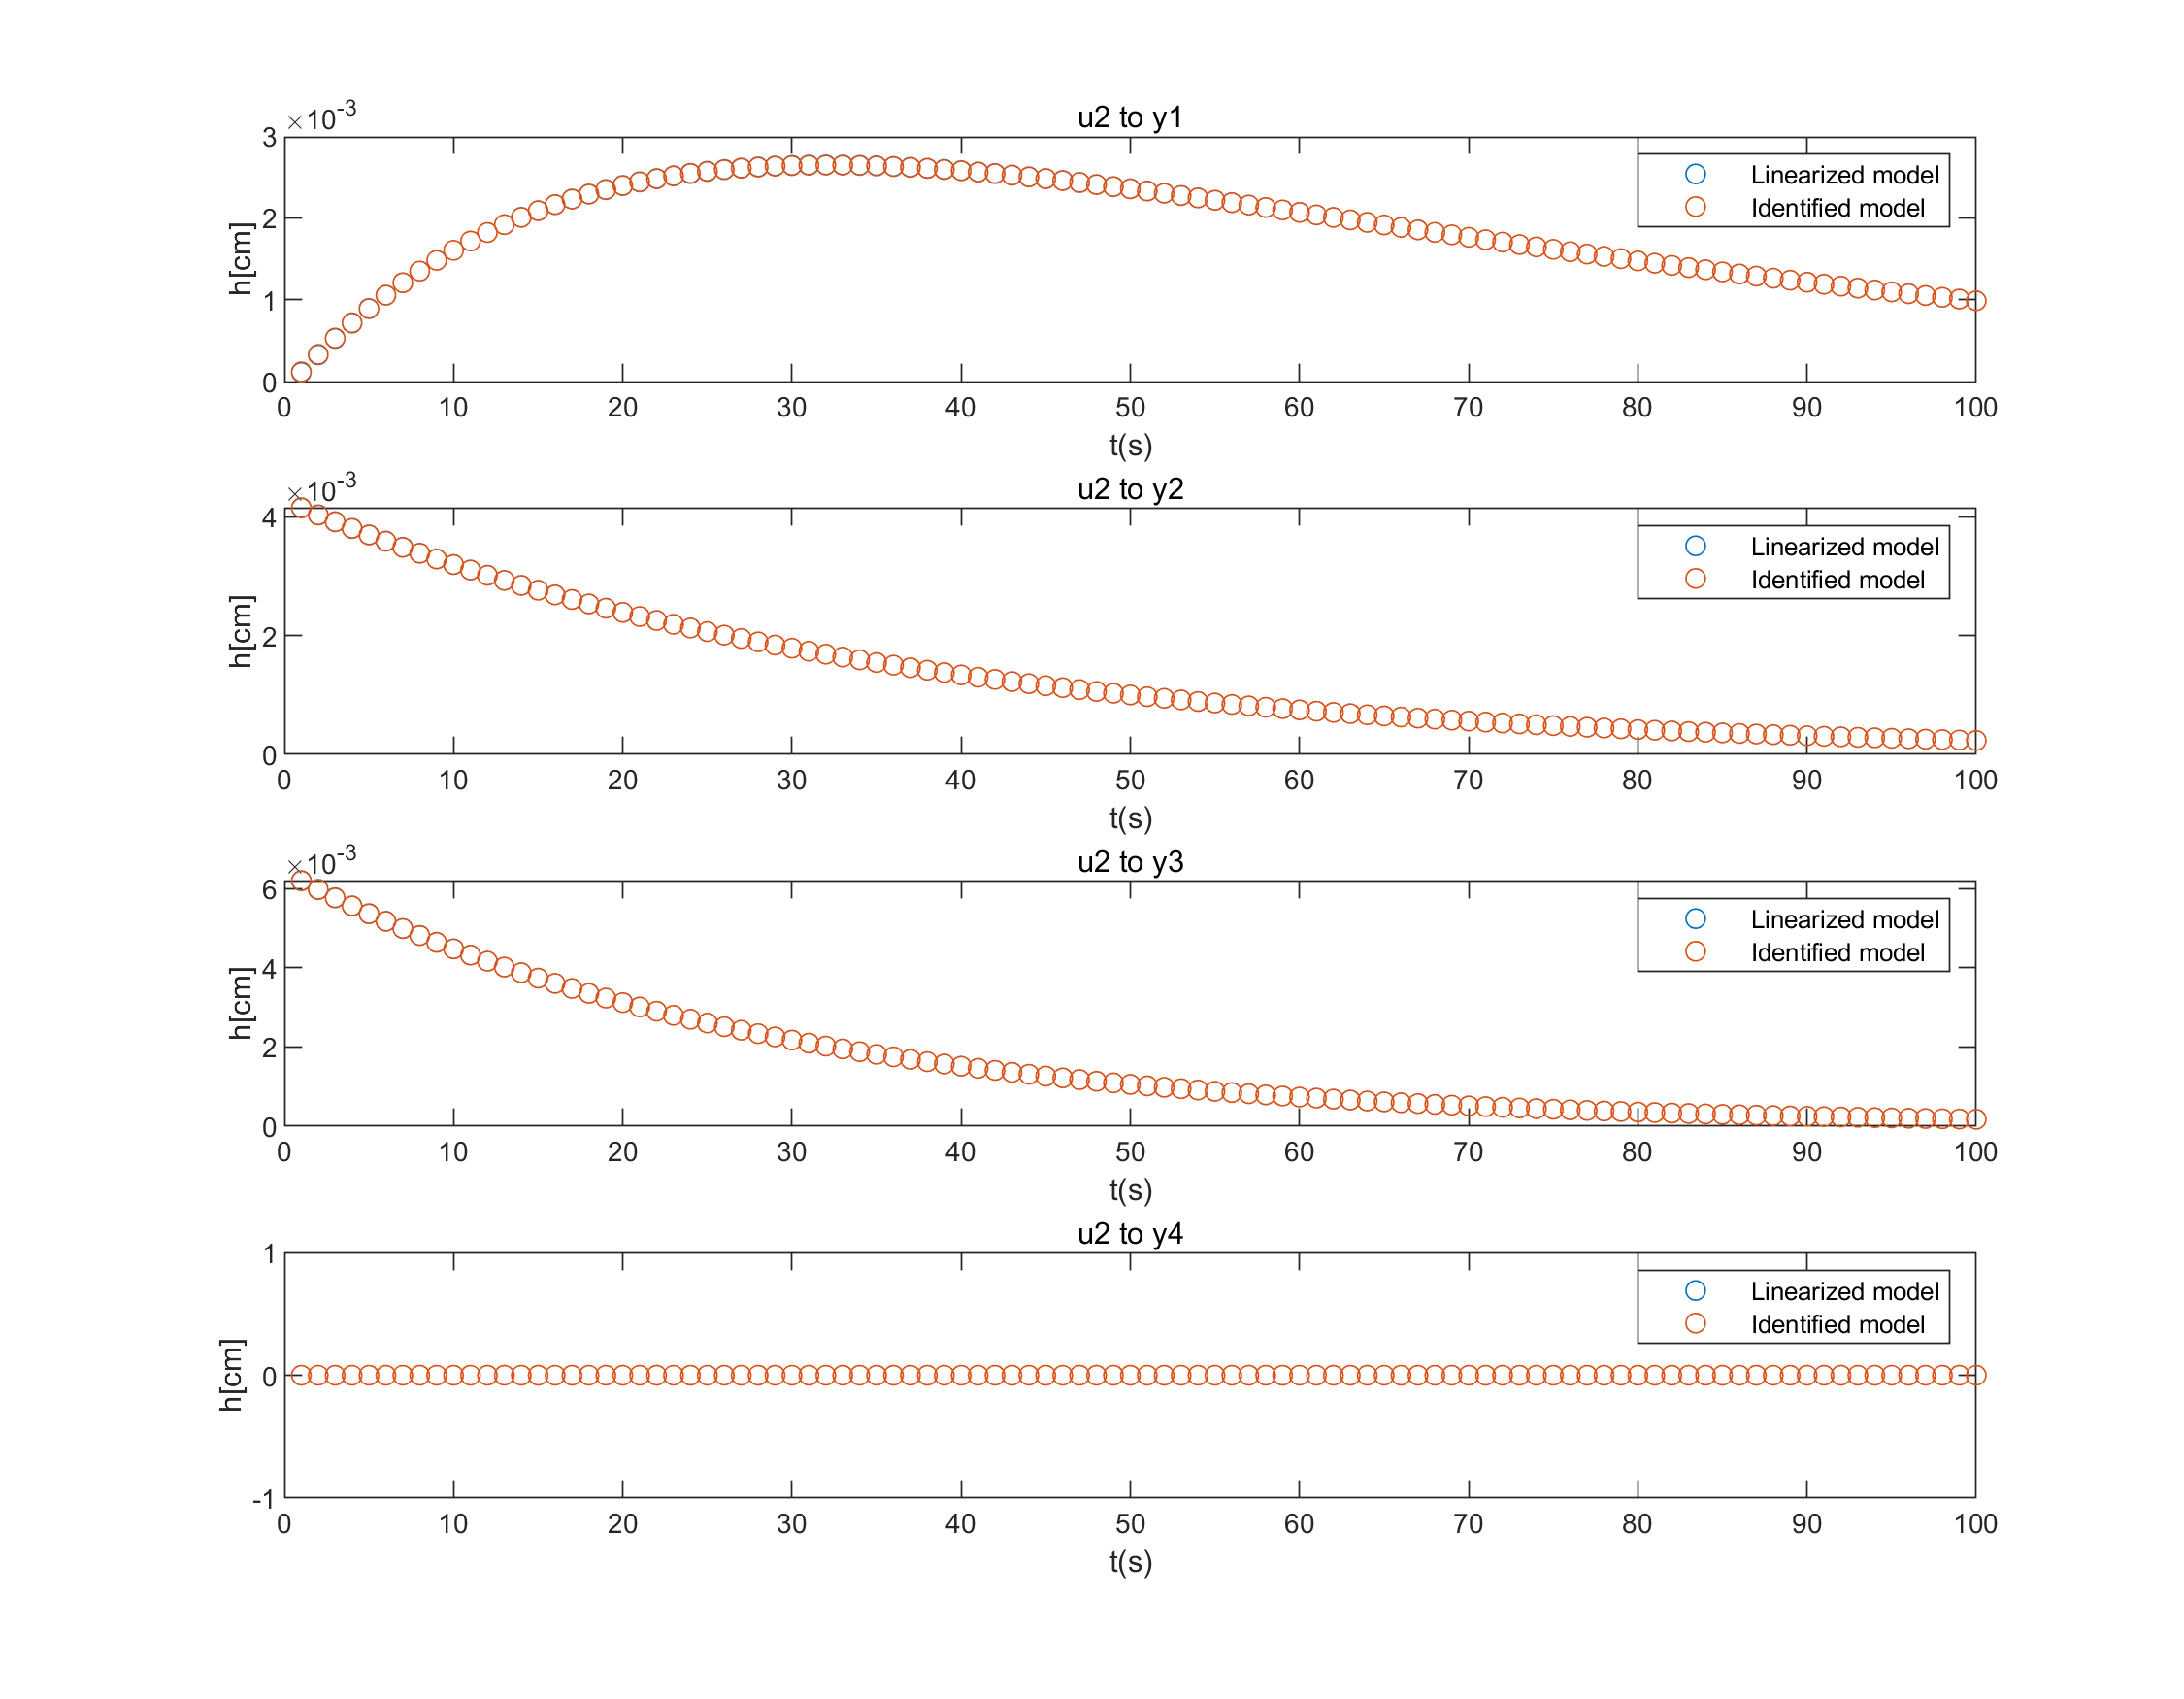


figure;
width=900;
height=700;
left=100;
bottem=100;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t_mp,mp_lin_u2_y1,'o',t_mp,mp_u2_y1,'o')
title('u2 to y1')
xlabel('t(s)');
ylabel('h[cm]');
legend("Linearized model","Identified model","Location", 'Northeast');
subplot(4,1,2)
plot(t_mp,mp_lin_u2_y2,'o',t_mp,mp_u2_y2,'o')
title('u2 to y2')
xlabel('t(s)');
ylabel('h[cm]');
legend("Linearized model","Identified model","Location", 'Northeast');
subplot(4,1,3)
plot(t_mp,mp_lin_u2_y3,'o',t_mp,mp_u2_y3,'o')
title('u2 to y3')
xlabel('t(s)');
ylabel('h[cm]');
legend("Linearized model","Identified model","Location", 'Northeast');
subplot(4,1,4)
plot(t_mp,mp_lin_u2_y4,'o',t_mp,mp_u2_y4,'o')
title('u2 to y4')
xlabel('t(s)');
ylabel('h[cm]');
legend("Linearized model","Identified model","Location", 'Northeast');